# Лабораторная работа №2 по СУвЭ

## Параметрический синтез и исследование цифровой системы управления с П-регулятором и объектом в виде последовательно включенных апериодического и интегрирующего звеньев из условия обеспечения заданного переходного процесса.

Определяем вариант задания:

ob.R = 0.1+unifrnd(-0.03,0.03);
ob.L = 0.02+unifrnd(-0.01,0.01);
ob.J = 100+unifrnd(-10,10);
ob.Ce = 2;
ob.Cm = ob.Ce;
save('data.mat', 'ob');

## Задание 1

Моделирование П-регулятора

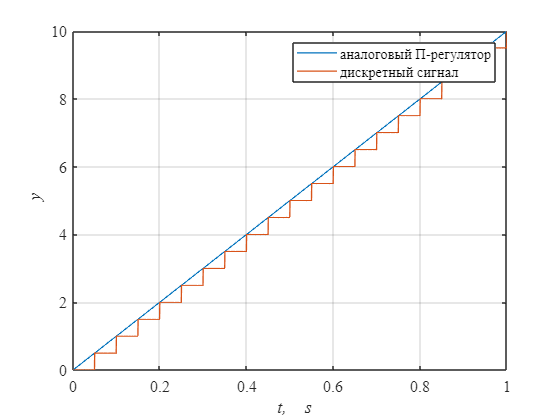

an.Kp = 10;%аналогавая система
dsc.Kp = 10;%дискретная система

Tmdl = 1;
To = 0.05;
warning off
simNew = sim('lab2_1.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.y(:,1);
an.y = simNew.y(:,2);
dsc.y = simNew.y(:,3);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'Linewidth', 1)
hold on
grid on
plot(t,dsc.y,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y')
legend('аналоговый П-регулятор', 'дискретный сигнал')

## **Задание 2**

### **Синтез системы с использованием «метода переоборудования»**

**синтез внутренного контура тока**

syms ia ua w e M
syms R L J Ce
syms dia dw
eq(1) = L*dia+ R*ia==ua-e;
eq(2) = J*dw==M;
eq(3) = e==Ce*w;
eq(4) = M==Ce*ia;

S1 = solve(eq,[dia dw e M]);
disp(collect(S1.dia, [ia w ua]))

$$\left(-\frac{R}{L}\right)\,\mathrm{ia}+\left(-\frac{\mathrm{Ce}}{L}\right)\,w+\frac{\mathrm{ua}}{L}$$

disp(collect(S1.dw, [ia w ua]))

$$\frac{\mathrm{Ce}}{J}\,\mathrm{ia}$$

A = [-R/L -Ce/L;
    Ce/J 0;];
B=[1/L; 0];
C = [1 0];
D = [0];

syms s
Wia = C*(s*eye(2) - A)^-1*B + D;
disp(collect(Wia, s))

$$\frac{J\,s}{\left(J\,L\right)\,s^{2}+\left(J\,R\right)\,s+{\mathrm{Ce}}^{2}}$$

Wia_spml = 1/(L*s+R);
disp(collect(Wia_spml, s))%пренебрегаем противоЭДС

$$\frac{1}{L\,s+R}$$

АЧХ и ФЧх разомкнутых систем

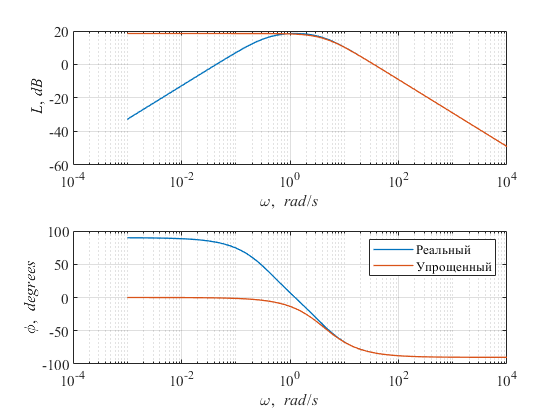

wfr = 10.^(-3:0.1:4);
sfr = 1i*wfr;
wia_tf = ob.J*sfr./(ob.J*ob.L*sfr.^2+ob.J*ob.R*sfr+ob.Ce^2);
wia_sm = 1./(ob.L*sfr+ob.R);

Lw_tf = 20*log10(abs(wia_tf));
phi_tf = angle(wia_tf)*180/pi;

Lw_sm = 20*log10(abs(wia_sm));
phi_sm = angle(wia_sm)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(wfr ,Lw_tf,'Linewidth', 1)
hold on
grid on
plot(wfr ,Lw_sm,'Linewidth', 1)
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(wfr ,phi_tf,'Linewidth', 1)
hold on
grid on
plot(wfr ,phi_sm,'Linewidth', 1)
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')
legend('Реальный', 'Упрощенный')

#### Расчет ПИ регулятора тока

syms Tt s
wol = 1/(Tt*s)

$$wol = \frac{1}{\mathrm{Tt}\,s}$$

wreg = wol/Wia_spml;
disp(collect(wreg, s))

$$\frac{L\,s+R}{\mathrm{Tt}\,s}$$

### Когда и почему можем пренебрегать противоЭДС 

АЧХ и ФЧХ замкнутой системы

Tt = 0.05 %при 0.5 система статическая, при увеличении Tt сильнее отличаются ФЧХ и АЧХ реальной и пренебрегаемой систем

Tt = 0.0500

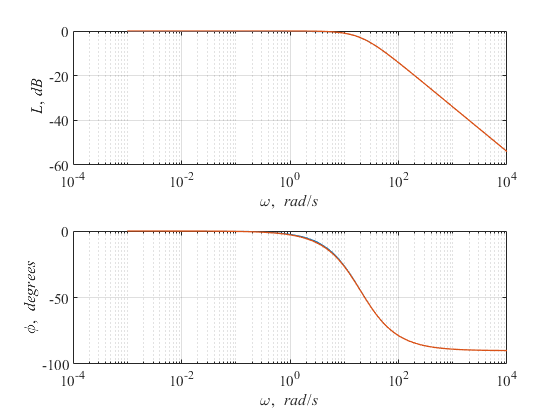

wfr = 10.^(-3:0.1:4);
sfr = 1i*wfr;
wia_tf = ob.J*sfr./(ob.J*ob.L*sfr.^2+ob.J*ob.R*sfr+ob.Ce^2);
wia_sm = 1./(ob.L*sfr+ob.R);
wreg_tf = (ob.L*sfr+ob.R)./(Tt*sfr);

wreal = wreg_tf.*wia_tf./(1+wreg_tf.*wia_tf);
wet = wreg_tf.*wia_sm./(1+wreg_tf.*wia_sm);

Lw_tf = 20*log10(abs(wreal));
phi_tf = angle(wreal)*180/pi;

Lw_sm = 20*log10(abs(wet));
phi_sm = angle(wet)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(wfr ,Lw_tf,'Linewidth', 1)
hold on
grid on
plot(wfr ,Lw_sm,'Linewidth', 1)
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(wfr ,phi_tf,'Linewidth', 1)
hold on
grid on
plot(wfr ,phi_sm,'Linewidth', 1)
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')

#### Моделирование работы контура тока

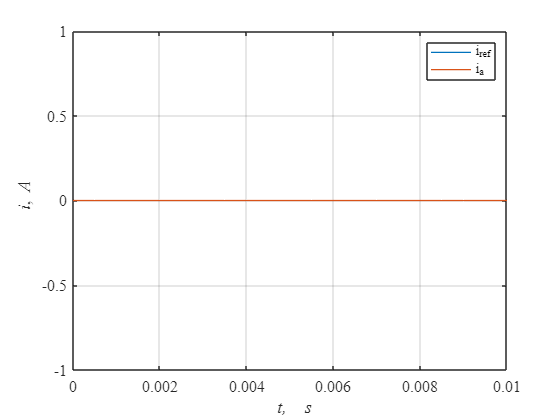

Tt = 0.001;
crl.Kpa = ob.L/Tt;
crl.Kia = ob.R/Tt;

Tmdl = 0.01;
To = 0.05;
warning off
simNew = sim('lab2_2my', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
isens = simNew.ia(:,3);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,isens,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i\rm, \itA')
legend('i_{ref}', 'i_a')

#### Расчет цифрового П-регулятора скорости

syms Tu Tt s

коэффициент датчика скорости

syms kdw
Wcrl = 1/(Tt*s+1);
Wob2 = Ce*kdw/(J*s)

$$Wob2 = \frac{\mathrm{Ce}\,\mathrm{kdw}}{J\,s}$$

передаточная функция раз. системы, настроенный на техн. оптиум

Tu=Tt;
wol = 1/(2*Tu*s*(Tu*s+1));
Wreg = wol/(Wcrl*Wob2);
disp(collect(Wreg, s))

$$\frac{J}{2\,\mathrm{Ce}\,\mathrm{Tt}\,\mathrm{kdw}}$$

#### Моделирование работы системы, настроенной на тех. оптиум

Tt = 0.005;

crl.Kpa = ob.L/Tt;
crl.Kia = ob.R/Tt;
spl.Tu = Tt;
kdw = 180/pi;
Tmdl = 0.1;

To=0.1*Tu

To=0.1*spl.Tu;
stl.Kpa = ob.J/2/ob.Ce/Tt./kdw;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_2bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_2bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_2bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_2bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_2bmy/Subsystem/Current Regulator/Sum1
lab2_2bmy/Subsystem/Current Regulator/Gain


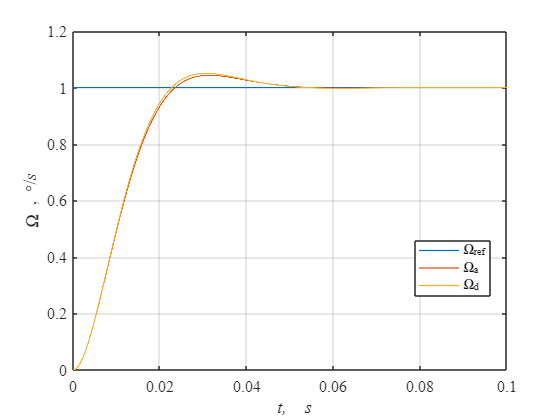

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 4.0*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 6.3*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 5.0*Tu 


#### To=1*Tu

To=1*spl.Tu;
stl.Kpa = ob.J/2/ob.Ce/Tt./kdw;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_2bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_2bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_2bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_2bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_2bmy/Subsystem/Current Regulator/Sum1
lab2_2bmy/Subsystem/Current Regulator/Gain


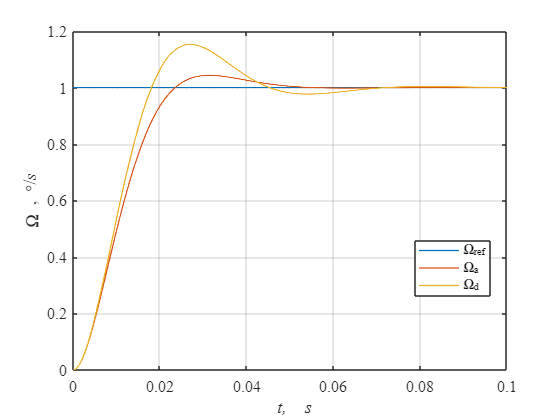

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.4*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 7.8*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 15.3*Tu 


## **Задание 3**

**Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового П-регулятора для случая вычислительной задержки ε = 0**

To=spl.Tu

To = 0.0050

Tmdl = 2;
for i = 1:10
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    warning off
    b = sim('lab2_3bmy.slx','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa))

end

Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f = 0.0028

Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f =     0.0028    0.0022


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f =     0.0028    0.0022    0.0015


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f =     0.0028    0.0022    0.0015    0.0008


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f =     0.0028    0.0022    0.0015    0.0008    0.0003


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f =     0.0028    0.0022    0.0015    0.0008    0.0003    0.0009


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f =     0.0028    0.0022    0.0015    0.0008    0.0003    0.0009    0.0018


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f =     0.0028    0.0022    0.0015    0.0008    0.0003    0.0009    0.0018    0.0028


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f =     0.0028    0.0022    0.0015    0.0008    0.0003    0.0009    0.0018    0.0028    0.0039


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f =     0.0028    0.0022    0.0015    0.0008    0.0003    0.0009    0.0018    0.0028    0.0039    0.0050


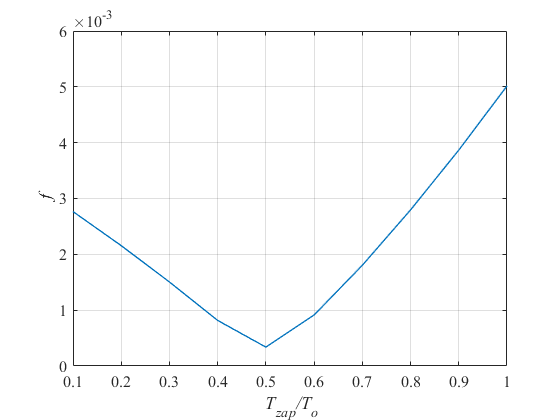

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

To=spl.Tu

To = 0.0050

clear f
Tmdl = 2;
for i = 1:10
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    warning off
    b = sim('lab2_3bmy.slx','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);

    %расчет времени переходного процесса аналоговой системы
    t0 = t(1);
    ya = wa;
    y0a = wa(1);
    yssa = wa(end);

    D5 = 0.05*abs(yssa-y0a);
    ind = abs(ya-yssa)<D5;
    tna = t(ind);
    t_tra = tna(1)-t0;

    %расчет времени переходного процесса дискретной системы
    y = wd;
    y0 = wd(1);
    yss = wd(end);

    D5 = 0.05*abs(yss-y0);
    ind = abs(y-yss)<D5;
    tn = t(ind);
    t_tr = tn(1)-t0;

    f1d = t_tr/spl.Tu
    f1a = t_tra/spl.Tu
    f(i)=f1a-f1d

end

Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f1d = 3.3800

f1a = 3.9500

f = 0.5700

Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f1d = 3.3800

f1a = 3.7700

f =     0.5700    0.3900


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f1d = 3.3800

f1a = 3.6300

f =     0.5700    0.3900    0.2500


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f1d = 3.3800

f1a = 3.5200

f =     0.5700    0.3900    0.2500    0.1400


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f1d = 3.3800

f1a = 3.4300

f =     0.5700    0.3900    0.2500    0.1400    0.0500


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f1d = 3.3800

f1a = 3.3500

f =     0.5700    0.3900    0.2500    0.1400    0.0500   -0.0300


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f1d = 3.3800

f1a = 3.3000

f =     0.5700    0.3900    0.2500    0.1400    0.0500   -0.0300   -0.0800


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f1d = 3.3800

f1a = 3.2500

f =     0.5700    0.3900    0.2500    0.1400    0.0500   -0.0300   -0.0800   -0.1300


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f1d = 3.3800

f1a = 3.2100

f =     0.5700    0.3900    0.2500    0.1400    0.0500   -0.0300   -0.0800   -0.1300   -0.1700


Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


f1d = 3.3800

f1a = 3.1800

f =     0.5700    0.3900    0.2500    0.1400    0.0500   -0.0300   -0.0800   -0.1300   -0.1700   -0.2000


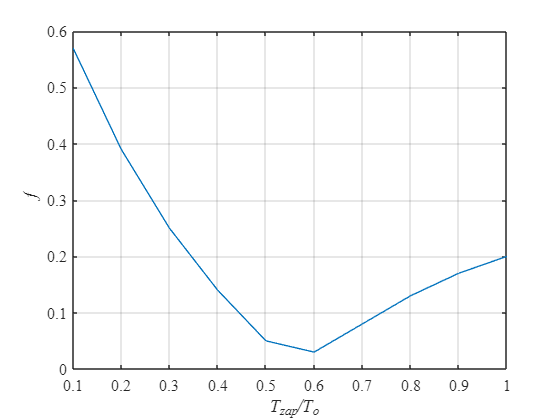

% % Изменения в коде для измерения разницы перерегулирования
% clear f
% Tmdl = 2;
% for i = 1:10
%     spl.Tz=i/10*To;
%     Tzap(i) = spl.Tz
%     warning off
%     warning off
%     b = sim('lab2_3bmy.slx','ReturnWorkspaceOutputs', 'on') ;
%     warning on
% 
%     t = b.w(:,1);
%     wa = b.w(:,3);
%     wd = b.w(:,4);
% 
%     t0 = t(1);
%     y = wd;
%     y0 = wd(1);
%     yss = wd(end);
%     
%     ya = wa;
%     y0a = wa(1);
%     yssa = wa(end);
%     % Измерение разницы перерегулирования (может потребоваться настройка)
%     f(i)= abs(max(y)-yss)/abs(y0-yss)
%     % Измерение разницы перерегулирования (может потребоваться настройка)
%     dy_d=abs(max(y)-yss)/abs(y0-yss)
%     dy_a=abs(max(ya)-yssa)/abs(y0a-yssa)
%     f(i)= abs(dy_a-dy_d)
% end

% Построение графика функционала

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To, abs(f), 'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

#### Перенастройка с помощью метода переоборудования

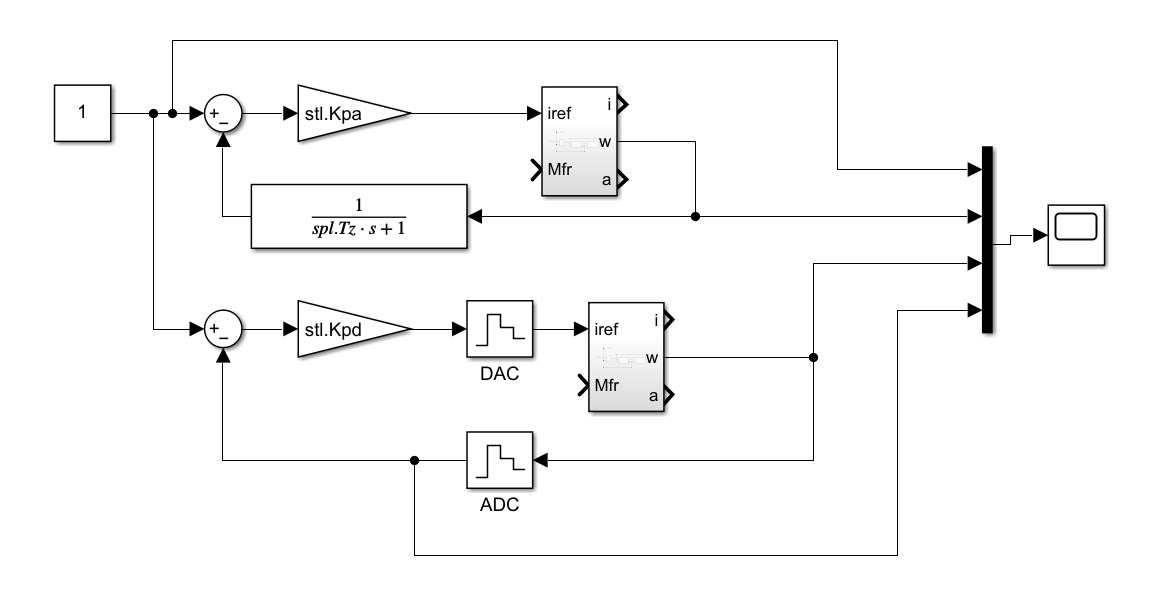

#### To=Tt

Tmdl = 0.1;
To=1*Tt;
spl.Tz = To*0.6

spl = struct with fields:
    Tu: 0.0210
    Tz: 0.0030


spl.Tu = Tt+ spl.Tz

spl = struct with fields:
    Tu: 0.0080
    Tz: 0.0030



stl.Kpa = ob.J/2/ob.Ce/spl.Tu/kdw;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_3bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


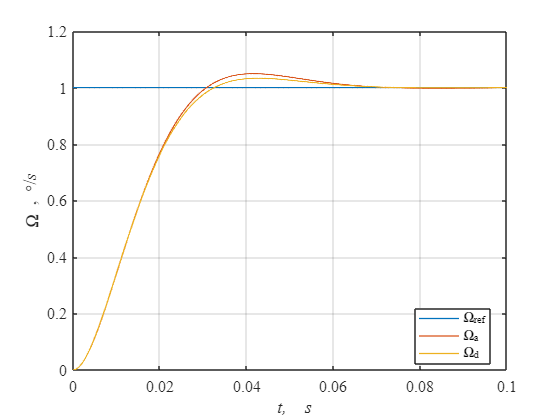

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.5*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 3.5*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 3.3*Tu 


#### To=2*Tt

To=2*Tt;
spl.Tz = To*0.5

spl = struct with fields:
    Tu: 0.0075
    Tz: 0.0050


spl.Tu = Tt+ spl.Tz

spl = struct with fields:
    Tu: 0.0100
    Tz: 0.0050



stl.Kpa = ob.J/2/ob.Ce/spl.Tu/kdw;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_31bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_31bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_31bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_31bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_31bmy/Subsystem/Current Regulator/Sum1
lab2_31bmy/Subsystem/Current Regulator/Gain


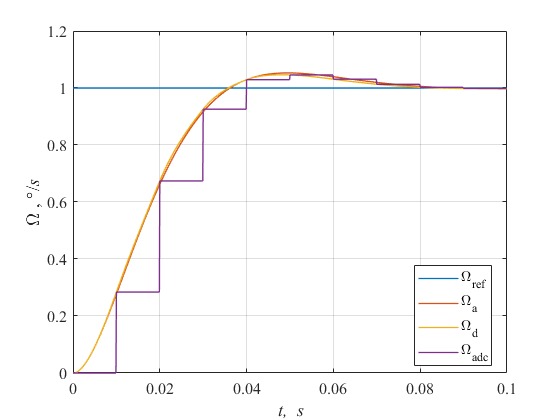

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);
wadc = simNew.w(:,5);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
plot(t,wadc,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','\Omega_{adc}','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.1*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 3.1*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 4.9*Tu 


## Задание 4

**Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового П-регулятора для случая вычислительной задержки ε = Т0.**

Tmdl = 0.15;
To=1*Tt;
spl.Tu = Tt;
stl.Kpa = ob.J/2/ob.Ce/spl.Tu/kdw;
stl.Kpd = stl.Kpa;

for i = 1:20
    spl.Tz=i/10*To
    Tzap(i) = spl.Tz;
    warning off
    simNew = sim('lab2_4bmy.slx', 'ReturnWorkspaceOutputs','on');
    warning on

    t = simNew.w(:,1);
    wa = simNew.w(:,3);
    wd = simNew.w(:,4);
    f(i) = trapz(t, abs(wd-wa));

end

spl = struct with fields:
    Tu: 0.0050
    Tz: 5.0000e-04


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 1.0000e-03


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0015


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0020


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0025


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0030


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0035


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0040


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0045


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0050


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0055


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0060


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0065


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0070


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0075


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0080


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0085


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0090


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0095


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0100


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


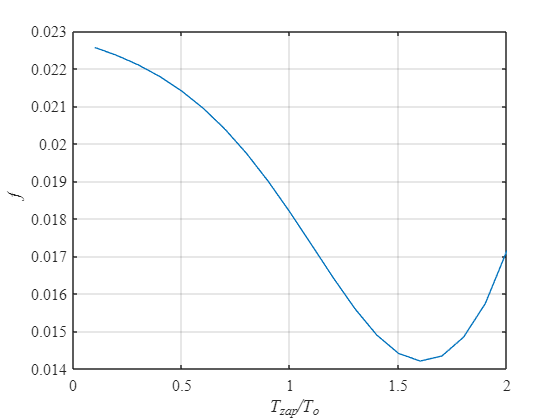

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

#### Перенастройка с помощью метода переоборудования

#### To=Tt

To=1*Tt;
spl.Tz = 1.6*To;
spl.Tu = Tt+ spl.Tz;

stl.Kpa = ob.J/2/ob.Ce/spl.Tu/kdw;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_4bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


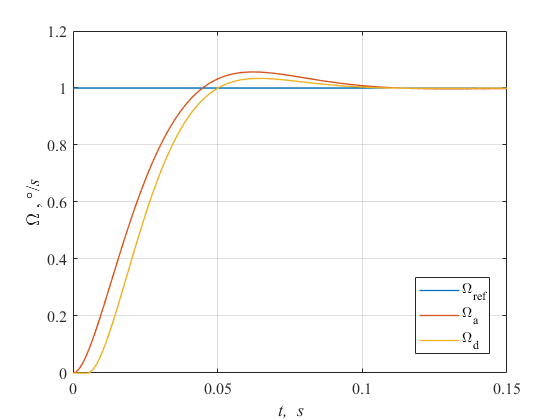

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.4*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 3.4*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 3.4*Tu 


#### To=2*Tt

To=2*Tt;
spl.Tz = 1.6*To;
spl.Tu = Tt+ spl.Tz

spl = struct with fields:
    Tu: 0.0210
    Tz: 0.0160



stl.Kpa = ob.J/2/ob.Ce/spl.Tu/kdw;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_4bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


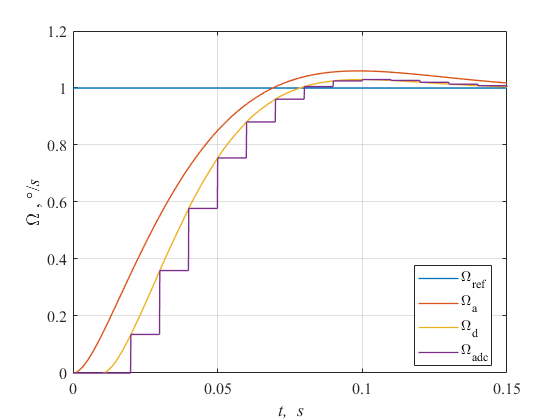

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);
wadc = simNew.w(:,5);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
plot(t,wadc,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','\Omega_{adc}','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.3*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 3.3*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 2.5*Tu 


## Задание 5

#### Моделирование работы системы, настроенной на биномиальный оптимум

Tt = 0.005;

crl.Kpa = ob.L/Tt;
crl.Kia = ob.R/Tt;
spl.Tu = Tt;
kdw = 180/pi;
Tmdl = 0.1;

To=0.1*Tu

To=0.1*spl.Tu;
stl.Kpa = ob.J/3/ob.Ce/Tt./kdw;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_2bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_2bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_2bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_2bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_2bmy/Subsystem/Current Regulator/Sum1
lab2_2bmy/Subsystem/Current Regulator/Gain


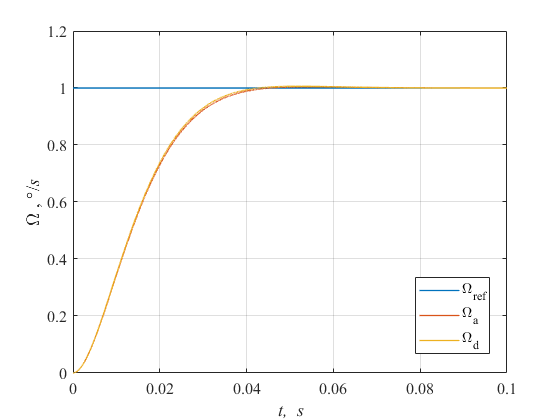

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 6.4*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 6.4*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.6*Tu 


#### To=1*Tu

To=1*spl.Tu;
stl.Kpa = ob.J/3/ob.Ce/Tt./kdw;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_2bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_2bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_2bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_2bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_2bmy/Subsystem/Current Regulator/Sum1
lab2_2bmy/Subsystem/Current Regulator/Gain


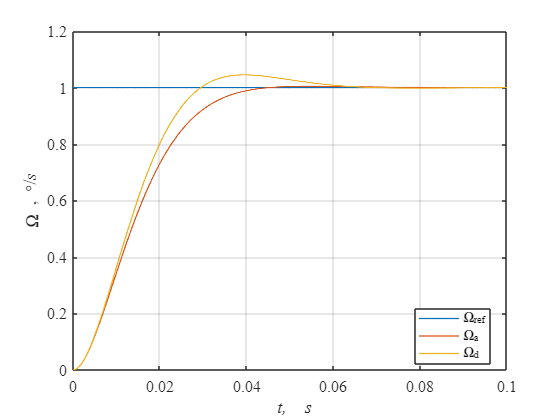

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 5.2*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 5.2*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 4.5*Tu 


## **Задание 3**

**Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового П-регулятора для случая вычислительной задержки ε = 0**

To=spl.Tu

To = 0.0050

Tmdl = 2;
for i = 1:10
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    warning off
    b = sim('lab2_3bmy.slx','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));

end

Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


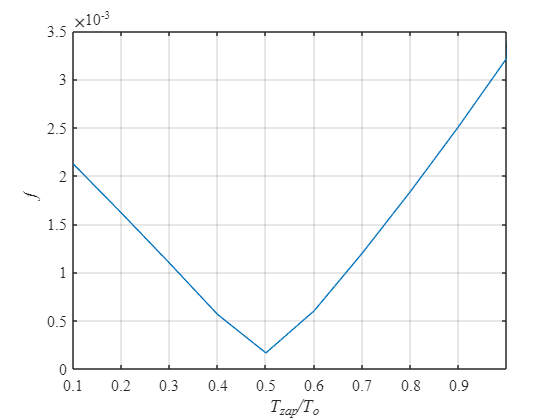

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')
xlim([0.1,1])

#### Перенастройка с помощью метода переоборудования

#### To=Tt

Tmdl = 0.1;
To=1*Tt;
spl.Tz = To/2

spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0025


spl.Tu = Tt+ spl.Tz

spl = struct with fields:
    Tu: 0.0075
    Tz: 0.0025



stl.Kpa = ob.J/3/ob.Ce/spl.Tu/kdw;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_3bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_3bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_3bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_3bmy/Subsystem/Current Regulator/Sum1
lab2_3bmy/Subsystem/Current Regulator/Gain


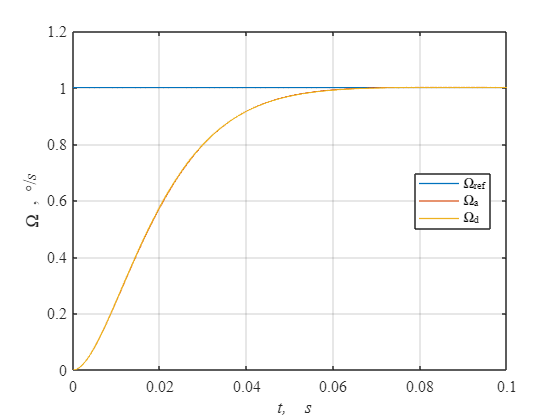

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 6.1*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 6.1*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


#### To=2*Tt

To=2*Tt;
spl.Tz = To/2

spl = struct with fields:
    Tu: 0.0075
    Tz: 0.0050


spl.Tu = Tt+ spl.Tz

spl = struct with fields:
    Tu: 0.0100
    Tz: 0.0050



stl.Kpa = ob.J/3/ob.Ce/spl.Tu/kdw;
stl.Kpd = stl.Kpa;

warning off
simNew = sim('lab2_31bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_31bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_31bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_31bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_31bmy/Subsystem/Current Regulator/Sum1
lab2_31bmy/Subsystem/Current Regulator/Gain


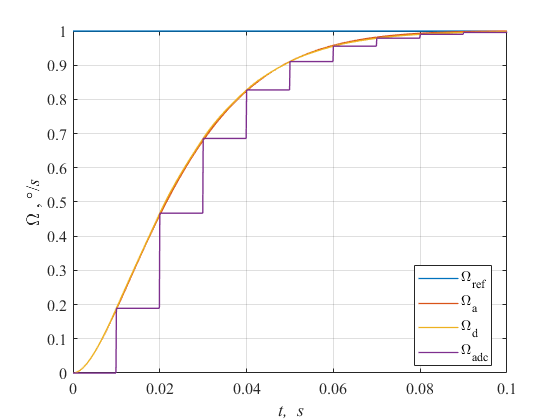

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);
wadc = simNew.w(:,5);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
plot(t,wadc,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','\Omega_{adc}','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 5.8*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 5.8*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


## Задание 4

**Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового П-регулятора для случая вычислительной задержки ε = Т0.**

Tmdl = 0.15;
To=1*Tt;
spl.Tu = Tt;
stl.Kpa = ob.J/3/ob.Ce/spl.Tu/kdw;
stl.Kpd = stl.Kpa;

for i = 1:20
    spl.Tz=i/10*To
    Tzap(i) = spl.Tz;
    warning off
    simNew = sim('lab2_4bmy.slx', 'ReturnWorkspaceOutputs','on');
    warning on

    t = simNew.w(:,1);
    wa = simNew.w(:,3);
    wd = simNew.w(:,4);
    f(i) = trapz(t, abs(wd-wa));

end

spl = struct with fields:
    Tu: 0.0050
    Tz: 5.0000e-04


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 1.0000e-03


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0015


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0020


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0025


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0030


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0035


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0040


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0045


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0050


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0055


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0060


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0065


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0070


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0075


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0080


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0085


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0090


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0095


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


spl = struct with fields:
    Tu: 0.0050
    Tz: 0.0100


Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


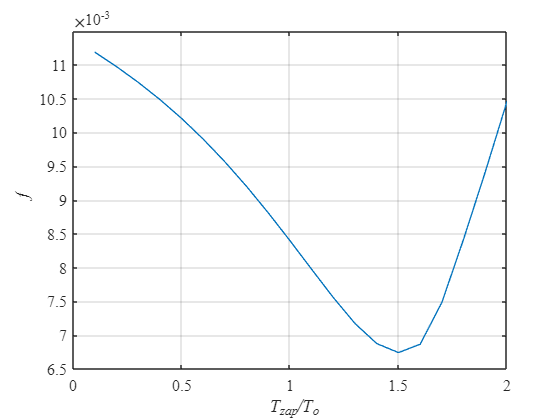

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

#### Перенастройка с помощью метода переоборудования

#### To=Tt

To=1*Tt;
spl.Tz = 1.5*To;
spl.Tu = Tt+ spl.Tz;

stl.Kpa = ob.J/3/ob.Ce/spl.Tu/kdw;
stl.Kpd = stl.Kpa;
Tmdl =0.3;
warning off
simNew = sim('lab2_4bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


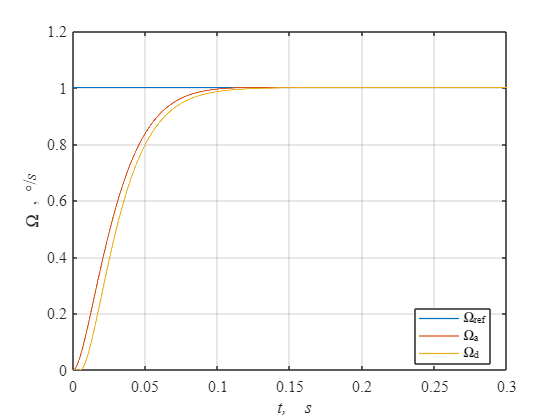

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 6.2*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 6.2*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


#### To=2*Tt

To=2*Tt;
spl.Tz = 1.6*To;
spl.Tu = Tt+ spl.Tz

spl = struct with fields:
    Tu: 0.0210
    Tz: 0.0160



stl.Kpa = ob.J/3/ob.Ce/spl.Tu/kdw;
stl.Kpd = stl.Kpa;
Tmdl = 0.3;
warning off
simNew = sim('lab2_4bmy.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab2_4bmy/Subsystem/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab2_4bmy/Subsystem/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE
lab2_4bmy/Subsystem/Current Regulator/Sum1
lab2_4bmy/Subsystem/Current Regulator/Gain


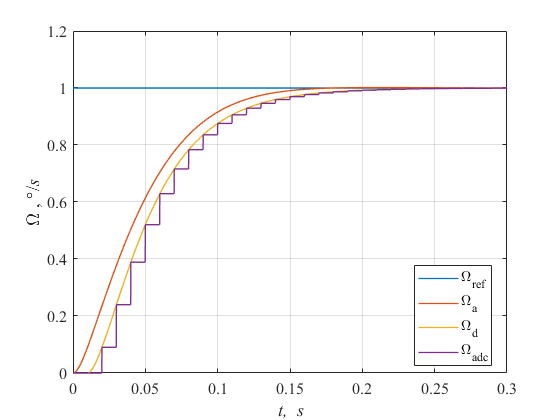

warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);
wadc = simNew.w(:,5);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
plot(t,wadc,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','\Omega_{adc}','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 6.3*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 6.3*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 
